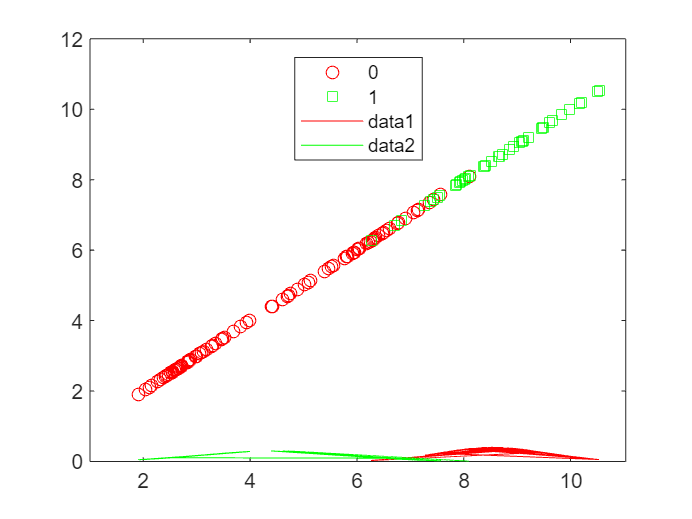

%preparing the vectors for 'virginica' against the rest, 'virginica as class 1 and others as class 0'
load fisheriris.mat
a=zeros(size(species));
for i=1:max(size(a))
    a(i)=isequal(species{i},'virginica');
end
label_vector=a;
instance_matrix=meas;
class1=meas(a==1,:);
class0=meas(a==0,:);

%class means
m1=mean(class1);
m0=mean(class0);

%class covariance matrix
s1=cov(class1);
s0=cov(class0);

%within class scatter matrix
sw=s0+s1;

%computing the LDA projection vector
v=inv(sw)*(m1-m0)';

%computing the projection score
score=meas*v;
figure;
gscatter(score(:,1),score(:,1),a,'rg','os');

%the class1
x1=score(a==1);

lm1=mean(x1);
lstd1=std(x1);
class1_pdf=mvnpdf(x1,lm1,lstd1);
%the class0
x0=score(a==0);
lm0=mean(x0);
lstd0=std(x0);
class0_pdf=mvnpdf(x0,lm0,lstd0);
figure(2)
hold on;
plot(x1,class1_pdf,'r');
plot(x0,class0_pdf,'g');
hold off